From [OPTIMALECM.tex](matlab:open('/home/joaquin/Desktop/CURRENT_TASKS/PAPERS_2020_onwards/OptimalECM/OPTIMALECM.tex')): 

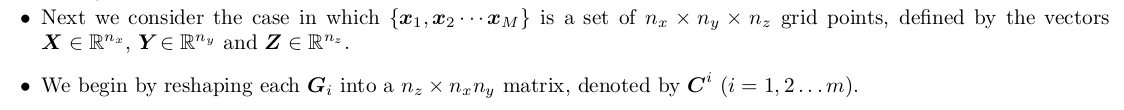

for iMODE = 1:NFUN
    Gi = G(iMODE,:) ;
    lx = length(x) ; 
    ly = length(y) ;
    lz = length(z);     
    % Reshaping Gi so that each row of C has the 
    % same z coordinate 
    C = reshape(Gi',lx*ly,[])';
    % To prove the above, uncomment the following line and check the outcome  
    % zzINIc  = reshape(xINI(:,3),lx*ly,[])';

The reshaping process can be asssessed by applying the same operation to the column of z-coordinates: the resulting matrix should be constant columnwise ---as shown below:

    % ---------------------------------------

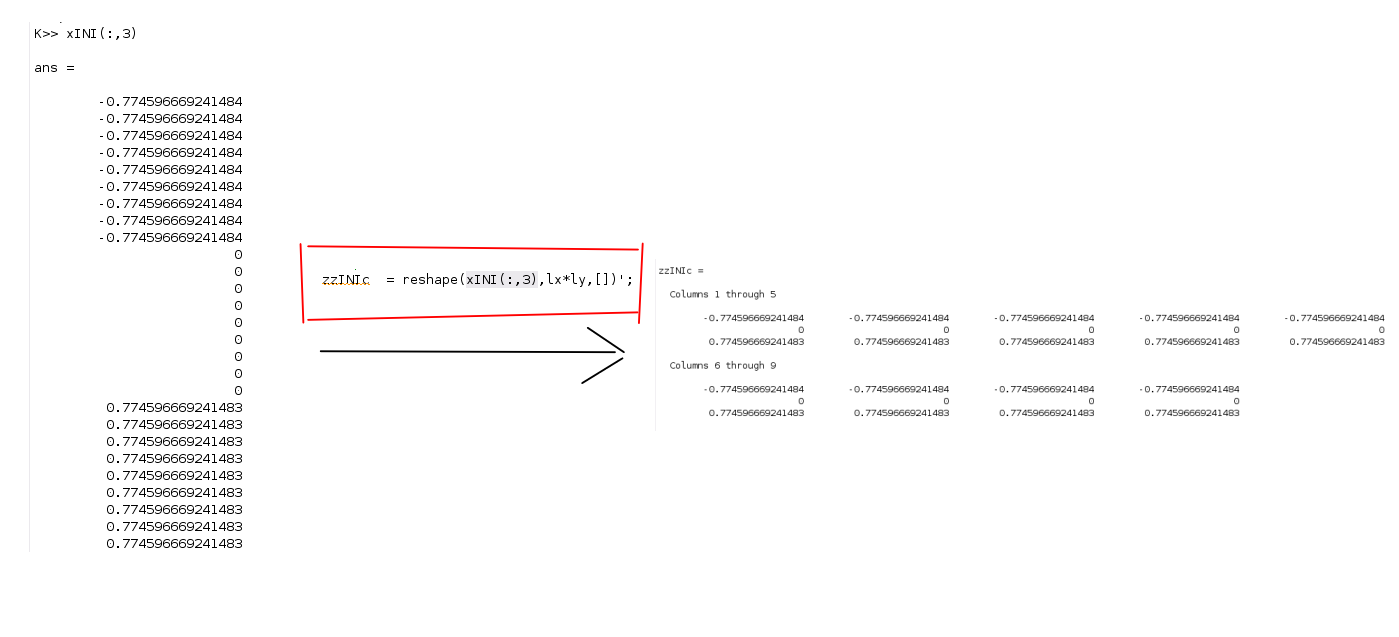

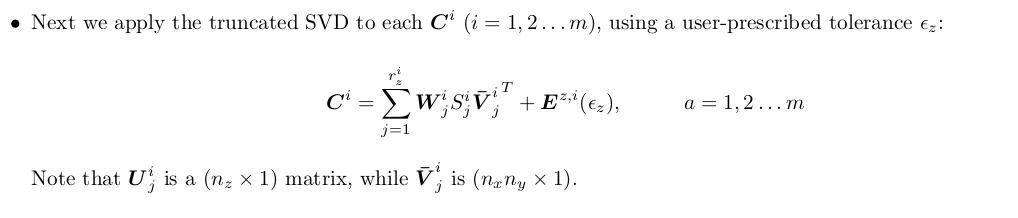

    epsilonZ = DATALOC.TOL_SVDfitting;
    DATASVD.RELATIVE_SVD = 1;
    [Wz,Sz,VbarXY] = RSVDT(C,epsilonZ,[],0,DATASVD) ;
    

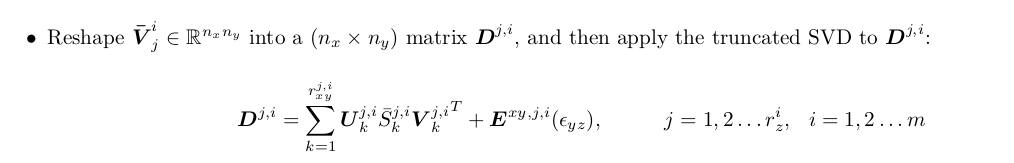

      for j = 1:length(rz)
        
        % Reshape VbarXY so that each row has the same
        %  x  coordinate 
        D = reshape(VbarXY(:,j),ly,[] )' ;  
        % To assess that the reshaping is correct, check this matrix
        XYcheck = xxINIc(1,:)' ; 
         XYcheckRESHAPE = reshape(XYcheck,ly,[] )' ;